# Maximizing Solar Panel Output for a Fixed Area

In this project, you will use MATLAB to formulate and solve an optimization problem: Given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Define the objective function in MATLAB (the energy function).

- Use a [problem-based optimization workflow](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html?searchPort=57359) to find the values of θ and r that maximize the energy output. Constrain the values: 0 ≤ θ ≤ 90 and 0.5 ≤ r ≤ 4

- Plot the objective function using `meshgrid` and [`surf`](https://www.mathworks.com/help/matlab/ref/surf.html) to visualize E(θ, r) as a 3D surface plot. Then, print the optimal angle, ratio, and corresponding energy output.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its tilt angle (theta) and aspect ratio (r). Check the Project Description for the energy formula and parameter definitions and use the image below as a guide:

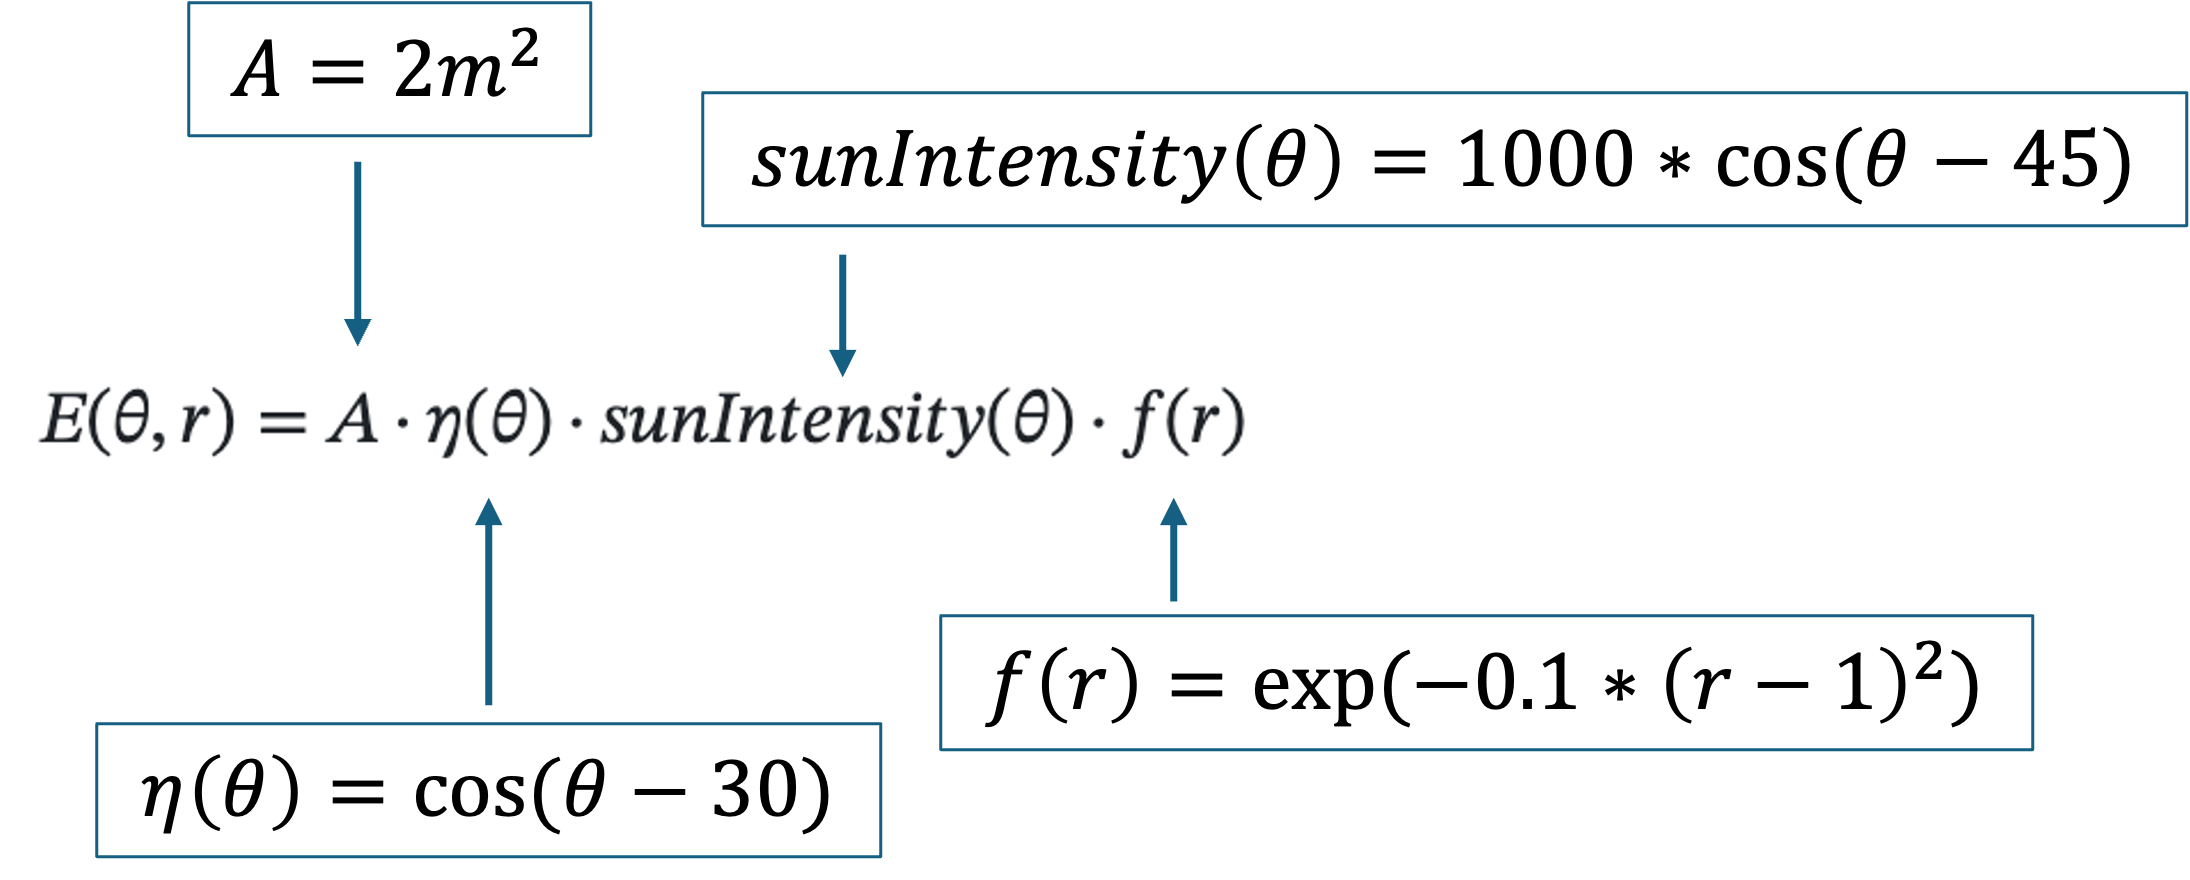

%% Task 1: Define the Objective Function

% Step 1: Define panel area (m^2)
A = 2;

% Step 2: Define efficiency based on tilt angle
nu = @(theta) cosd(theta - 30);

% Step 3: Define sunlight intensity
sun_intensity = @(theta) 1000 .* cosd(theta - 45);

% Step 4: Define shape efficiency factor
fr = @(r) exp(-0.1 .* (r - 1).^2);

% Step 5: Define total energy output
energy_function = @(theta,r) ...
    A .* nu(theta) .* sun_intensity(theta) .* fr(r);

## Task 2: Implement the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. This MATLAB [doc page](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) will be helpful.

%% Task 2: Implement the Optimization Function

% Step 1: Create maximization problem
solar_problem = optimproblem("ObjectiveSense","maximize");

% Step 2: Define optimization variables
theta = optimvar("theta", ...
    "LowerBound",0, ...
    "UpperBound",90);

r = optimvar("r", ...
    "LowerBound",0.5, ...
    "UpperBound",4);

% Step 3: Build optimization expressions
nu_objective = cos((theta - 30) .* pi/180);

sun_intensity_objective = ...
    1000 .* cos((theta - 45) .* pi/180);

fr_objective = exp(-0.1 .* (r - 1).^2);

energy_objective = A .* nu_objective .* ...
    sun_intensity_objective .* fr_objective;

% Step 4: Set the objective
solar_problem.Objective = energy_objective;

% Step 5: Set initial guess
initial_guess.theta = 45;
initial_guess.r = 2;

% Step 6: Solve the problem
[solution,max_energy] = solve(solar_problem,initial_guess);


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Store results
optimal_theta = solution.theta;
optimal_ratio = solution.r;
optimal_energy = max_energy;

## Task 3: Output the Results

Use the appropriate plotting function to plot E(θ, r) and visualize the energy surface. Print the optimal tilt angle and aspect ratio, and corresponding energy output.

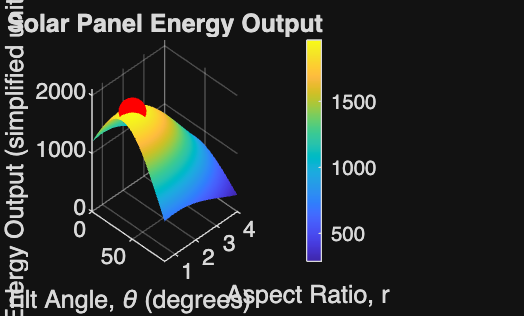

%% Task 3: Output the Results

% Step 1: Create grid values
theta_values = 0:1:90;
r_values = 0.5:0.1:4;

% Include the exact optimal values in the grid
theta_values = sort(unique([theta_values optimal_theta]));
r_values = sort(unique([r_values optimal_ratio]));

[theta_grid,r_grid] = meshgrid(theta_values,r_values);

% Step 2: Calculate energy on the grid
energy_grid = energy_function(theta_grid,r_grid);

% Calculate energy at the exact optimum
optimal_energy_plot = ...
    energy_function(optimal_theta,optimal_ratio);

% Step 3: Create surface plot
figure
surf(theta_grid,r_grid,energy_grid)

% Step 4: Label the plot
xlabel("Tilt Angle, \theta (degrees)")
ylabel("Aspect Ratio, r")
zlabel("Energy Output (simplified units)")
title("Solar Panel Energy Output")

colorbar
grid on
shading interp
xlim([0 90])
ylim([0.5 4])
zlim([0 2100])
view(45,30)

% Mark the optimal point
hold on

plot3(optimal_theta,optimal_ratio,optimal_energy_plot, ...
    "ro", ...
    "MarkerSize",9, ...
    "MarkerFaceColor","r", ...
    "LineWidth",1.5)

hold off


% Step 5: Print results
fprintf("Optimal tilt angle: %.2f degrees\n",optimal_theta);

Optimal tilt angle: 37.50 degrees


fprintf("Optimal aspect ratio: %.2f\n",optimal_ratio);

Optimal aspect ratio: 1.00


fprintf("Maximum energy output: %.2f energy units\n", ...
    optimal_energy);

Maximum energy output: 1965.93 energy units


## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?